# Chapter 1 Exercise 7

Identificazione di un sistema a due dimensioni.

Si effettua una stima dei parametri di OFFSET e SLOPE con due dataset. Si nota come la stima ottenuta con il primo dataset, variando gli ingressi, permette di avere un modello sempre più vicino al modello reale (soprattutto all'inizio), con un errore basso e deviazione minore.

## Prima stima

clc                  % Clear Command Window
clear                
clear all
Ndata=100;           % 100 punti dati... sul libro c'è scritto 1000
Nrepeat=1000;        % 1000 esperimenti ripetuti.... sul libro c'è scritto 10^5 = 100.000
a0=0.1; b0=0;        %parametri del sistema

 true system *y0=a0*u + b0 *       

*a0* è la pendenza (slope) della retta, *b0* (offset) è il valore di intersezione con l'asse quando u=0 

stdNoise=1;         % assegno il valore 1 alla variabile che rappresenta la deviazione standard del rumore di disturbo

La variabile *stdNoise* rappresenta la deviazione standard del rumore che verrà aggiunto al segnale di output del sistema. 

Un valore più grande di *stdNoise* indica un rumore più intenso, che può rendere la stima dei parametri del sistema più difficile. Al contrario, un valore più piccolo di stdNoise indica un rumore meno influente, che può semplificare la stima dei parametri.

Impostare *stdNoise*=1 potrebbe creare un livello di rumore ragionevolmente significativo e realistico per valutare l'accuratezza delle stime dei parametri del sistema.

u1=linspace(-3,3,Ndata);                % primo set di input che varia da -3 a +3 variando di 0.06 per un totale di 100 elementi
u1=u1(:);                               % rendo u1 vettore colonna
u2=linspace(2,5,Ndata);                 % secondo vettore di input che varia da 2 a 5 con passo 0.03 per avere 100 elementi
u2=u2(:);

y10=a0*u1+b0;                           % creiamo il vettore di output rispetto l'input u1 (struttura del sistema vista sopra)
y20=a0*u2+b0;                           % output per il secondo set di dati con input u2

for r=Nrepeat:-1:1                      % loop sul numero di esperimenti ripetuti da 1000 a 1
	noise=stdNoise*randn(size(y10));    % con "randn" creo un vettore con distrubuzione normale della stessa dimensione di y10. Si ottiene il rumore gaussiano bianco moltiplicando tale distribuzione con stdNoise
    % Il rumore Gaussiano è dato da: A_wnoise = k + 5*randn(size(A))
    % k è la media e 5 rappresenta la deviazione standard
    % In questo caso si ha media 0 e deviazione standard 1, quest'ultima specificata da stdNoise
	y1=y10+noise;                       % aggiungendo il rumore ai dati di output veri y10 e y20 si ottengono i vettori y1 e y2 (simulo così un'uscita reale)
	y2=y20+noise;
	

La regressione lineare è un metodo statistico utilizzato per analizzare la relazione tra una variabile di output (o variabile dipendente) e una o più variabili di input (o variabili indipendenti). L'obiettivo della regressione lineare è trovare una relazione lineare che leghi la variazione dell'output in base alle variabili di input

Nella sua forma più semplice, la regressione lineare cerca di trovare una retta che meglio approssima i dati, definita dall'equazione:

y = b0 + b1*x1 + b2*x2 + ... + bn*xn

- y rappresenta l'output

- b0 rappresenta l'intercetta (il valore di y quando tutte le variabili indipendenti sono zero; l'interesezione con l'asse)

- b1, b2, ..., bn rappresentano i coefficienti di regressione (che misurano l'effetto delle variabili indipendenti sull'output; il peso del relativo input)

- x1, x2, ..., xn rappresentano le variabili indipendenti (gli input)

*b_i *è l'equivalente di* a0* (quest'ultima uguale, però, per ogni input) dell'equazione scritta sopra

L'obiettivo della regressione lineare è trovare i valori ottimali per i coefficienti di regressione in modo da minimizzare l'errore tra i valori predetti dalla retta di regressione e i valori reali dell'output. **Questo viene generalmente fatto utilizzando il metodo dei minimi quadrati, che cerca di ridurre la somma dei quadrati degli errori tra i valori predetti e i valori reali. **L'obiettivo di un calcolatore di regressione è trovare i migliori valori di *α* e *β (per Y*=*α*+*βX)* in modo che la somma degli errori al quadrato sia la più piccola possibile.

Il metodo dei minimi quadrati è una tecnica utilizzata per stimare i parametri di un modello matematico in modo che la somma dei quadrati degli errori tra i dati osservati e i valori predetti dal modello sia minimizzata. In pratica, cerca di trovare i valori dei parametri che forniscono la migliore approssimazione ai dati sperimentali.

Nell'esercizio in esame, l'obiettivo è stimare i coefficienti di regressione dell'equazione lineare y0=a0*u + b0 . Si crea una matrice K che conterrà sulle righe gli ingressi di ciascuna equazione, per la precisione sulla prima colonna si ha l'ingresso che viene moltiplicato per lo slope a0 e nella seconda colonna il l'ingresso che viene moltiplicato per l'offeset b0; ovvero 1.

Per la precisione vengono create le matrici di regressione *K1* e *K2*. *K1* contiene *u1* come prima colonna e una colonna di 1 come seconda colonna, mentre *K2* contiene u2 come prima colonna e una colonna di 1 come seconda colonna.

y sarà un vettore colonna di 100 elementi (ho 100 equazioni) e infine un vettore dei coefficienti che conterrà i valori di a0 e b0.

Volendo stimare proprio i coefficienti a0 e b0, allora la matrice degli ingressi è considerata come una matrice dei coefficienti e il vetore dei coefficienti come vettore delle incognite che chiamiamo Est.

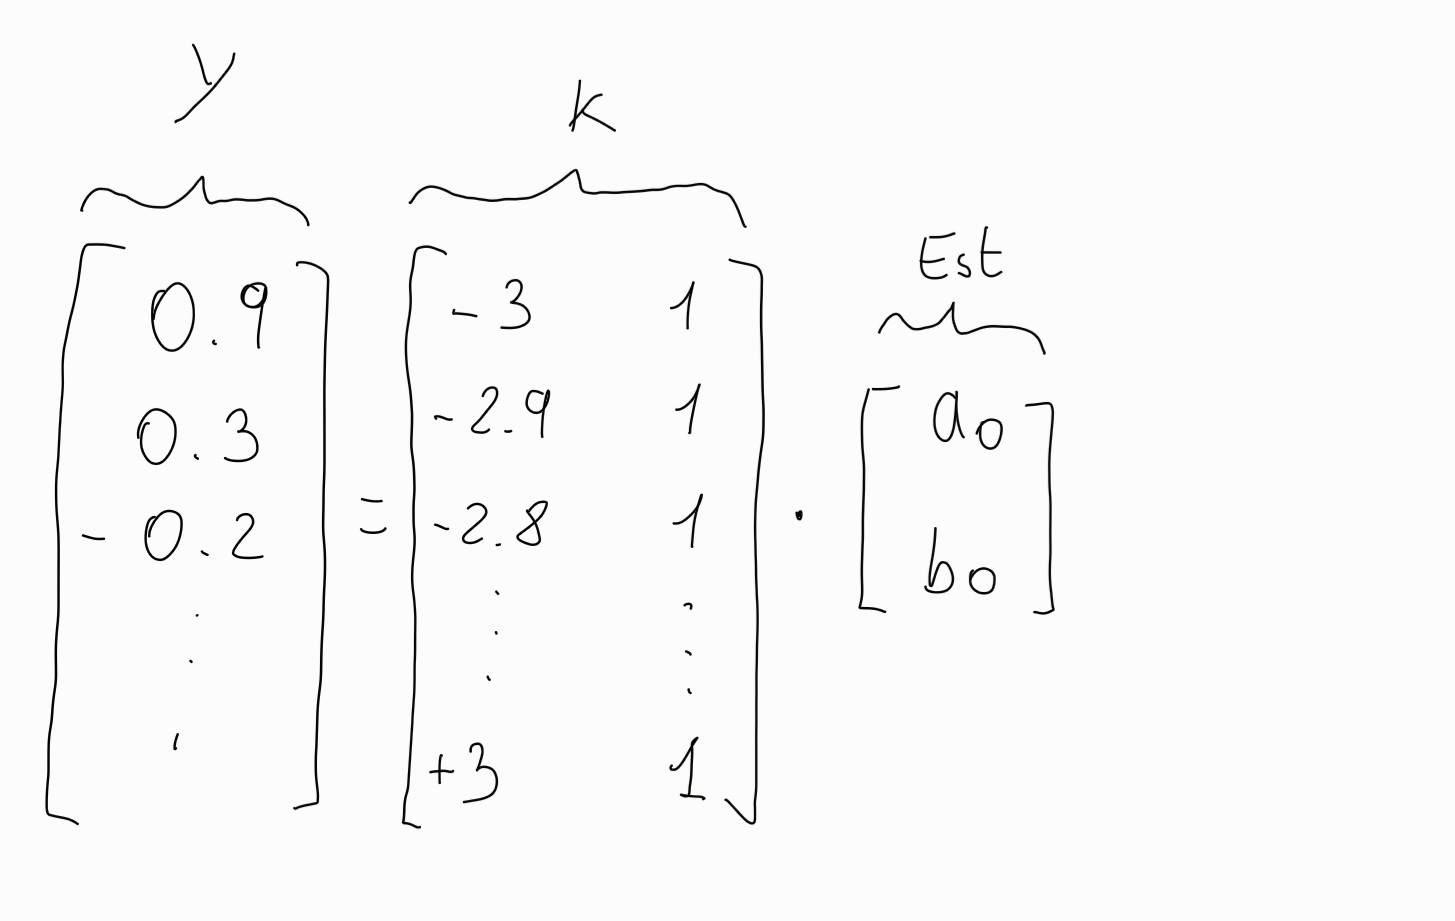

Il metodo dei minimi quadrati viene utilizzato per trovare i valori di a0 e b0 che minimizzano la differenza tra i dati osservati (vettore *y*) e i dati stimati (vettore *K*Est*).

Quindi, l'obiettivo è trovare il vettore dei parametri *Est* tale che *K*Est* sia il più vicino possibile a *y*.

Per comprendere come si arriva all'equazione finale , dobbiamo considerare il modello lineare che stiamo utilizzando per approssimare la relazione  tra l'uscita *y* e gli ingressi *u* attraverso i coefficienti di regressione.

L'equazione del modello in forma matriciale:  

y = K * Est

L'obiettivo del metodo dei minimi quadrati è trovare il vettore Est che minimizzi la quantità: 

||y - K * Est||^2

dove ||.|| indica la norma Euclidea.

La soluzione ottimale può essere trovata impostando la derivata parziale rispetto a Est uguale a zero:

2 * K' * (y - K * Est) = 0

Risolvendo questa equazione per Est, otteniamo la seguente formula:

Est = [(K' * K)^-1] * (K' * y)

	K1=[u1 ones(size(u1))];             % create K-matrix first data set. Ho una colonna di 1 perchè non ho un ingresso u che è moltiplicato per b0 (nell'equazione di sopra)
	K2=[u2 ones(size(u2))];             % create K-matrix second data set

- la matrice *K1* ha dimensioni 100x2 (due il sistema è composto da 100 equazioni in 2 variabili  →  SUPERFLUE) e il vettore *y1* ha dimensione 100x1 (rappresenta i termini noti delle 100 equazioni del nostro sistema lineare), *Est1* ha solo due righe, una per ogni variabile:

| -3      1 |        |  x1  |                | 0.9  |

| -2.9   1 |        |        |        =      | 0.3  |            il vettore delle incognite x (il nostro *Est*) deve avere un num. di righe = num. colonne di K;

| -2.8   1 |        |  x2  |                | -0.2 |            Il vettore delle y deve avere un numero di righe = al numero di righe di K

Est1=K1\y1;                         % This is the numerical stable calculation of (K1'K1)^-1*K1'y1
Est2=K2\y2;                         % viene calcolata la stima dei parametri: Stima ai minimi quadrati di modelli lineari

Il comando *Est=K\y* utilizza l'operatore backslash \ in MATLAB per calcolare la soluzione del sistema di equazioni lineari nella forma *K*Est=y*. Questo calcolo determina i valori ottimali per i parametri *Est* in modo che l'errore tra *K*Est* e *y* sia minimizzato.

K è una matrice rettangolare 100x2 colonne, mentre y è un vettore 100x1 →  allora *K\y* restituisce una **soluzione dei minimi quadrati** al sistema di equazioni *K*Est=y*.

L'operazionerestituisce un vettore di dimensione 2x1; due coefficienti di regressione ottimali (i due parametri: la pendenza (coefficiente angolare) e l'offset (intercetta)) che meglio approssimano i dati di output *y* in base ai valori degli ingressi *u * →  sono le due soluzioni del nostro sistema lineare	

In sostanza, il comando *Est*=*K\y* calcola i valori dei parametri *Est* che ottimizzano la regressione lineare dei dati *y* rispetto ai regressori *K*. Questi parametri stimati vengono quindi utilizzati per costruire un modello approssimato che si adatta ai dati osservati.

La prima colonna di ogni matrice contiene le stime dei parametri di pendenza (slope) del sistema, mentre la seconda colonna contiene le stime dei parametri di offset. Quindi, ogni riga delle matrici *Est1* e *Est2* rappresenta una stima dei parametri per un singolo esperimento ripetuto. Est1 contiene le stime dei parametri basate sui dati generati utilizzando il primo set di input (*u1*), mentre *Est2* contiene le stime dei parametri basate sui dati generati utilizzando il secondo set di input (*u2*)

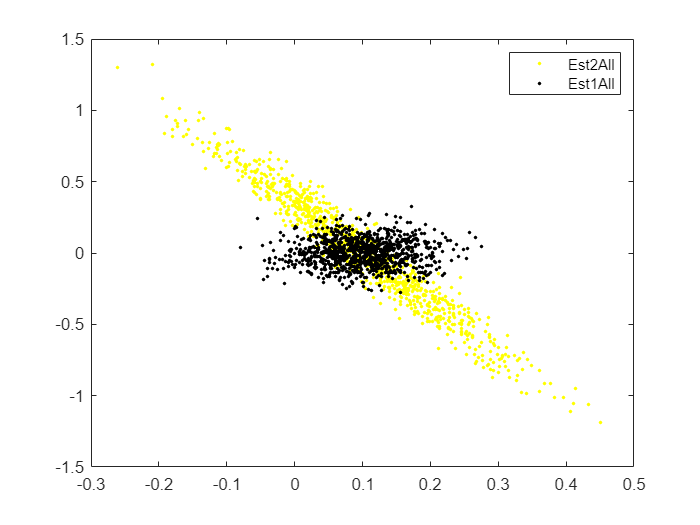

	Est1All(r,:)=Est1';     % Tutte le varie stime (per ogni esperimento ripetuto) vengono salvate sulle righe in queste matrici
	Est2All(r,:)=Est2';

end

'DG_SetFontSize' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\nikyg\Desktop\Uni\Data model - Naso\AllMatlabFIles\Graphics

Change the MATLAB current folder or add its folder to the MATLAB path.

Le stime dei parametri vengono salvate nelle matrici *Est1All* e *Est2All* per ogni esperimento ripetuto

Seguendo il ciclo for, per ogni indice "*r*", viene calcolato un nuovo valore di "*noise*" per via della funzione "*randn*" che restituisce valori sempre differenti, di conseguenza, ad ogni ripetizione, cambiano i valori di *y1* e *y2* → **NON** cambiano i valori di *K1* e *K2* → cambiano i valori di *Est1* e *Est2  *→  ciascun nuovo valore di queste ultime due variabili vengono salvati nella r-esima riga di *Est1All* e *Est2All*; ecco perchè *Est1* ed *Est2* sono vettori 2x1 mentre *Est1All* e *Est2All* sono vettori 1000x2 (nel salvare il valore di *Est1* ed *Est2* ad ogni iterazione, questi vettori vengono trasposti  →  ecco perchè le ALL hanno due colonne). **Ho tante righe quanti sono gli esperimenti totali, ovvero 1000 = *****NRep*****. Sulla r-esima riga leggo il valore della pendenza = *****a***** (prima colonna) e dell'offset = *****b***** (seconda colonna) dell'esperimento r-esimo**

% create the first plot. L'obiettivo è vedere con quale dataset riusciamo
% ad avere la stima dei parametri più vicina al valore reale di a0=0.1 e
% b0=0
FigNum=8;

figure(FigNum)
clf
plot(Est2All(:,1),Est2All(:,2),'.y',Est1All(:,1),Est1All(:,2),'.k') % grafico delle stime dei paramentri per entrambi i set di dati
legend('Est2All','Est1All')
DG_SetFontSize(12)
DG_SetTraceWidth(2,'*',FigNum,1)
%DG_SetTraceTint(30,1,FigNum,1)
xlabel('Slope')                 % sull'asse x la pendenza
ylabel('Offset')

L'utilizzo dei punti anziché linee connesse indica che i parametri sono stati stimati in modo discreto per ogni esperimento.

Vengono rappresentati i punti stimati per il parametro "Slope" (pendenza) sull'asse x e "Offset" (offset) sull'asse y. Questi punti corrispondono ai risultati delle 1000 stime per entrambi i set di dati. 

I **punti gialli** ("*Est2All(:,1),Est2All(:,2)*") rappresentano le **stime dei parametri** ottenute **utilizzando il secondo set di dati di input (*****u2, y2*****)**, dimostrano una maggiore variabilità nelle stime dei parametri per il secondo set di dati, mentre i **punti neri **("*Est1All(:,1),Est1All(:,2)*") rappresentano le **stime dei parametri** ottenute **utilizzando il primo set di dati di input (*****u1, y1*****) **che sono più coerenti e concentrate intorno a un valore comune. La stima dei coefficienti di regressione per il primo set di dati (u1, y1) è più precisa e converge verso il valore atteso di slope = 0.1 e offset = 0.

Ciò che cambia tra un set di dati e l'altro è SOLAMENTE l'ingresso u. Infatti u1 è diverso da u2 (sono sempre 100 elementi ma variano in intervalli differenti e con passo differente), y10 e y20 sono costruiti allo stesso modo, dunque sono differenti in quanto diverso è l'ingresso u utilizzato, infine y1 e y2 sono costruiti partendo da y10 e y20 con l'aggiunta della variabile noise che è però uguale per entrambi ad ogni iterazione.

**La differenza nella dispersione dei punti tra i due set di dati è dovuta da diversi fattori, come ****la distribuzione dei punti dati (ovvero il differente dataset di input u citato sopra)****, la presenza di rumore (che varia ad ogni r-esima iterazione e che quindi mi fa avere diverse stime). **

**Se i punti sono raggruppati intorno ai valori veri dei coefficienti di regressione (*****a0 = 0.1, b0 = 0*****), ciò indica che i modelli stimati tendono ad avvicinarsi ai valori attesi.**

## Nuovo input

% vengono generati nuovi input in un intervallo diverso per valutare i modelli stimati
% Si verifica l'uscita che otteniamo, utilizzando i parametri stimati in
% precedenza e questi nuovi input sottostanti, quanto sia vicina all'uscita
% reale nota

u1_new=linspace(0,10,40);               % Nuovo input che varia da 0 a 10 e contiene 40 elementi  →  il passo è di 0.25
u1_new=u1_new(:);                       % rendo u1 vettore colonna
u2_new=u1_new+(u1_new(2)-u1_new(1))/2;  % viene creato u2 spostando ogni punto del vettore u1 di una metà del passo(0.25/2 = 0.125  →  u2 = u1 + 0.125)


Stando a ciò che è stato fatto in precendenza, ora cambiano gli input u1 e u2 (ovvero è come se nel sistema precedente cambiassero K1 e K2) e ci chiediamo di quanto varia y mantenendo però gli stessi valori di x (ovvero di Est1 ed Est2, cioè i parametri che moltiplicano gli ingressi) ricavati in precedenza; questo viene fatto per ogni esperimento  →  per ogni r-esimo valore

for r=100:-1:1                                           % evaluate all the estimated models per 100 esperimenti 
    ym1All1(:,r)=(Est1All(r,1)*u1_new'+Est1All(r,2))';   % Viene calcolato l'output in base al nuovo input ma utilizzando le stime dei parametri precedenti
    u1Plot(:,r)=u1_new;                                  % salvo in questo modo gli input per poter avere una matrice di dimensione uguale alla matrice ymAll, ovvero 40x100
    ym2All1(:,r)=(Est2All(r,1)*u2_new'+Est2All(r,2))';   % non ho nulla che moltiplica EstAll(r,2) in quanto, nell'eq. originale, non avevo nulla che moltiplicava il parametro b0 (contenuto appunto nella seconda colonna)
    u2Plot(:,r)=u2_new;                                  % ogni r-esima colonna contiene il vettore colonna u_new creato sopra
end

## Plot dell'output con il nuovo input

% Create the 2nd plot
FigNum=9;
figure(FigNum)
clf

real1 = a0*u1_new + b0;         % creo la reale uscita del sistema (con i parametri noti di a0=0.1 e b0=0) con i nuovi input per poterla confrontare nel grafico
real2 = a0*u2_new + b0;
subplot(2,2,1)                 
plot(u1Plot,ym1All1,'k')        % la specifica di u1Plot permette di far "rientrare" tutto l'output (i 40 valori di ym1All) nel range di u1Plot (ovvero tra 0 e 1). In pratica determino l'asse delle ascisse
axis([0 10 -5 5])
hold on
plot(u1Plot,real1,'r')
legend('dataset1')
DG_SetFontSize(12)
DG_SetTraceWidth(1,'*',FigNum,1)
%DG_SetTraceTint(30,2,FigNum,2)
ylabel('Modeled output'),xlabel('Time (s)')

subplot(2,2,2)       
plot(u2Plot,ym2All1,'k')            % idem per sopra
axis([0 10 -5 5])
hold on
plot(u2Plot,real2,'r')
legend('dataset2')
DG_SetFontSize(12)
DG_SetTraceWidth(1,'*',FigNum,2)
DG_SetTraceTint(30,'*',FigNum,2)

## Plot degli errori

subplot(2,2,3)                   % plot the errors on the modelled output
u1=linspace(0,10,30);            % Creo un nuovo input di 30 elementi da 0 a 10 con passo 0.33
u1=u1(:);                        % rendo u1 colonna
u2=u1+(u1(2)-u1(1))/2;           % aggiungo 0.166 ad ogni valore di u1

clear u1Plot u2Plot
for r=100:-1:1                                                      % calculate the errors
    e1All1(:,r)=(Est1All(r,1)*u1'+Est1All(r,2))'-(a0*u1'+b0)';      % differenza tra l'uscita ottenuta con il nuovo input e sempre i parametri stimati inizialmente e un'uscita ottenuta sempre con il nuovo input ma con i parametri noti di a0=0.1 e b0=0
    u1Plot(:,r)=u1;
    e2All1(:,r)=(Est2All(r,1)*u2'+Est2All(r,2))'-(a0*u2'+b0)';
    u2Plot(:,r)=u2;
end

plot(u2Plot(:),e2All1(:),'.b',u1Plot(:),e1All1(:),'.y')             % plot degli errori appena calcolati (la specifica di uPlot è per gli stessi motivi indicati sopra)
axis([0 10 -1 1])
DG_SetFontSize(12)
xlabel('Time')
ylabel('Error y')
legend('e2All1','e1All1')

DG_SetTraceWidth(1,'*',FigNum,3)
DG_SetTraceTint(30,1,FigNum,3)
xlabel('Time (s)')


LA DEVIAZIONE STANDARD È UNA MISURA DI DISPERSIONE O VARIABILITÀ DEI DATI ALL'INTERNO DI UN SET DI OSSERVAZIONI. INDICA QUANTO I DATI SONO DISTRIBUITI INTORNO ALLA MEDIA,  SE LA DEVIAZIONE STANDARD È ALTA, SIGNIFICA CHE I DATI SONO MOLTO DISPERSI, MENTRE SE È BASSA, SIGNIFICA CHE I DATI SONO RAGGRUPPATI ATTORNO ALLA MEDIA.

LA DEVIAZIONE STANDARD VIENE CALCOLATA NEL SEGUENTE MODO:

- CALCOLA LA MEDIA DEI DATI, CHE RAPPRESENTA IL VALORE CENTRALE O LA TENDENZA CENTRALE DEL SET DI DATI.

- PER OGNI DATO NEL SET, CALCOLA LA DIFFERENZA TRA IL DATO E LA MEDIA.

- ELEVA AL QUADRATO OGNI DIFFERENZA PER ELIMINARE GLI EFFETTI DELLE DIFFERENZE POSITIVE E NEGATIVE.

- CALCOLA LA MEDIA DEI QUADRATI DELLE DIFFERENZE, CHIAMATA VARIANZA.

- PRENDI LA RADICE QUADRATA DELLA VARIANZA PER OTTENERE LA DEVIAZIONE STANDARD.

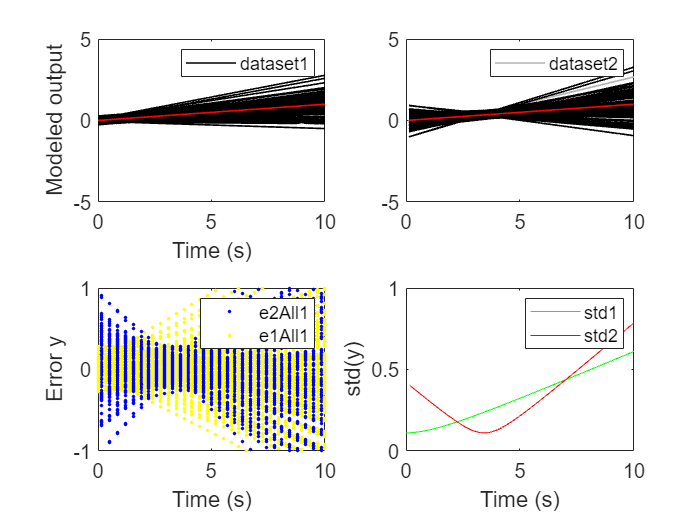

subplot(2,2,4)                                               % plot the std. dev. of the errors
plot(u1,std(e1All1,0,2),'g',u2,std(e2All1,0,2),'r')
legend('std1','std2')
axis([0 10 0 1])
DG_SetFontSize(12)

% DG_SetTraceWidth(2,'*',FigNum,4)
% DG_SetTraceTint(30,2,FigNum,4)
xlabel('Time (s)')
ylabel('std(y)')

%DG_Init4PDF(gcf, 4.5);        % fixing the size, half standard height
%DG_MakePDF('FigIdent8b.pdf', gcf);

%print -dpdf FigIdent8


Il secondo grafico è composto da quattro sotto-grafici.  Vengono valutati i modelli stimati nell'intervallo di input [0, 10]; ogni curva rappresenta un modello stimato. **Se le curve si avvicinano alla linea retta ideale y = a0*u + b0 (rossa), ciò suggerisce che i modelli stimati approssimano correttamente il vero sistema.**

- Il primo sotto-grafico mostra l'output del modello stimato per il primo set di dati nel range di input compreso tra 0 e 10, poiché sono stati eseguiti 1000 esperimenti ripetuti, il grafico mostra 1000 diverse linee corrispondenti alle diverse stime dei parametri. **Si nota che per i valori iniziali di u1 si ha un'uscita molto vicina a quella reale (rossa). All'aumentare di u1 si ha un discostamento dell'uscita stimata rispetto quella reale (rossa). Naturalmente ho alcune rette quasi sovrapponibili con quella rossa in base alla r-esima iterazione che ha dei coefficienti di a0 (in Est1All prima colonna) e di b0 (in Est1All seconda colonna). **Se le linee sono concentrate in una regione stretta intorno a un valore specifico, significa che le stime dei parametri sono relativamente coerenti e producono risultati simili per diversi dati di input, inoltre indica che il modello è in grado di approssimare in modo accurato i dati di input nell'intervallo considerato. In altre parole, il fascio di linee nere rappresenta la variabilità dell'output del modello al variare delle stime dei parametri, fornendo un'indicazione della precisione delle stime e della robustezza del modello.

- Il secondo sotto-grafico mostra l'output del modello stimato per il secondo set di dati nel range di input compreso tra 0 e 10. Entrambi i sotto-grafici hanno l'asse x che rappresenta il tempo (INPUT) e l'asse y che rappresenta l'output del modello stimato. Questi grafici mostrano come i modelli stimati approssimano i dati per i rispettivi set di input. Le linee sembrano avere un offset maggiore e inoltre risultano più distanziate, ciò indica che le stime dei parametri producono un'ampia variazione nell'output del modello per il secondo set di dati di input. *Ciò può essere dovuto a diversi fattori, come una sensibilità diversa del modello ai valori di input e una maggiore incertezza nelle stime dei parametri. ***Il modello restituisce una stima vicina all'uscita reale, con i valori di a0 (Est2All prima colonna) e b0 (Est2All seconda colonna) per un ingresso che varia tra 2.5 e 4.5. Per gli altri valori dell'ingresso u2 il modello stimato diverge maggiormente rispetto all'uscita reale (rossa)**

- Il terzo sotto-grafico rappresenta gli errori tra l'output del modello stimato e l'output reale. Vengono calcolati gli errori sottraendo i valori attesi dei dati di output dai valori predetti utilizzando i modelli stimati. **Se gli errori sono distribuiti attorno allo zero, con una distribuzione simmetrica intorno al valore medio, ciò indica che i modelli stimati hanno una buona aderenza ai dati di output attesi. **Le linee gialle corrispondono all'errore per il primo set di dati di input (`u1`) mentre le linee blu corrispondono all'errore per il secondo set di dati di input (`u2`). Quando le linee gialle e blu si sovrappongono, significa che gli errori per entrambi i set di dati di input sono simili in quel punto. Questo suggerisce che le stime dei parametri del modello, per quel determinato valore di input, si adattano bene a entrambi i set di dati e che l'errore tra l'output stimato e i valori veri dell'output è comparabile. Quando le linee sono più larghe significa che l'errore associato a quei punti di dati è più elevato. Nell'intorno di 3 secondi (VALORE DELL'INPUT) l'errore è più piccolo per il secondo set di dati con *u2*, per poi divergere. Invece, per il primo set di dati con *u1*, l'errore è più piccolo all'inizio (t=0) e poi diverge.

- Il quarto sotto-grafico mostra la deviazione standard degli errori nel range di input compreso tra 0 e 10, fornendo un'indicazione della dispersione degli errori per entrambi i set di dati. La linea verde rappresenta la deviazione standard dell'errore per il primo set di dati *u1*, mentre la linea rosa rappresenta la deviazione standard dell'errore per il secondo set di dati *u2*. L'intersezione nei punti (2.38; 0.16) e (7; 0.41)  indicano che, per quei due valori specifici sull'asse x(in quel determinato istante di tempo), la deviazione standard dell'errore è la stessa per entrambi i set di dati, ovvero il modello ha una precisione simile per entrambi i set di dati, cioè l'errore associato al modello è comparabile tra i due set di dati; ciò si evince nel grafico degli errori precedente, infatti in tali punti le linee blu e gialle sono sovrapponibili. Per il resto dei punti, la deviazione standard dell'errore è diversa per i due set di dati. Per la precisione la linea verde ha un andamento crescente, ciò significa che la variabilità dell'errore aumenta all'aumentare del valore di input e che l'accuratezza del modello tende a diminuire man mano che ci si allontana dai valori di input iniziali. Per la linea rosa invece la diminuzione iniziale della deviazione standard dell'errore indica che il modello è relativamente accurato nella previsione dell'output per valori di input sempre più vicini al punto di minimo (intorno ai 3.5). Tuttavia, una volta superato il punto di minimo, la deviazione standard dell'errore inizia a crescere rapidamente e quindi il modello è meno adatto o meno accurato per stimare l'output quando *u2* si allontana dal punto di minimo.

disp('Covariance matrix experiment 1'),disp(cov(Est1All))   

Covariance matrix experiment 1
    0.0032    0.0001
    0.0001    0.0090



covarianza tra i valori di Est1All, cioè tra i valori di offset (prima colonna) e slope (seconda colonna) per ciascun esperimento (riga)

Gli elementi della seconda diagonale mostrano una covarianza di 0.0001, quindi bassa correlazione. La covarianza NON va da -1 a +1

disp('Covariance matrix experiment 2'),disp(cov(Est2All))

Covariance matrix experiment 2
    0.0126   -0.0439
   -0.0439    0.1617



La covarianza misura la relazione lineare tra due variabili. Valori positivi indicano una correlazione positiva, mentre valori negativi indicano una correlazione negativa. La covarianza tra una variabile e se stessa (sulla diagonale principale della matrice) rappresenta la varianza di quella variabile.  Valori di covarianza elevati tra due variabili possono indicare una dipendenza o una relazione significativa.

La covarianza tra la prima variabile e la seconda variabile è -0.0473, dunque una correlazione negativa o inversa tra le variabili. In altre parole, quando il valore di una variabile aumenta il valore dell'altra variabile tende a diminuire.

disp('Correlation matrix experiment 1'),disp(corrcoef(Est1All))
disp('Correlation matrix experiment 2'),disp(corrcoef(Est2All))

Correlation matrix experiment 1
    1.0000    0.0238
    0.0238    1.0000



Correlation matrix experiment 2
    1.0000   -0.9717
   -0.9717    1.0000



La correlazione è una misura normalizzata della relazione lineare tra due variabili e varia tra -1 e 1. Una correlazione di 1 indica una correlazione positiva perfetta, mentre una correlazione di -1 indica una correlazione negativa perfetta. Valori vicini a 0 indicano una scarsa correlazione o l'assenza di relazione lineare tra le variabili. Sulla diagonale ho l'autocorrelazione, ovvero quanto la variabile è legata a se stessa  →  è 1, al di fuori della diagonale abbiamo la correlazione tra le due variabili, nel nostro caso quanto la variabile 1 è influenzata/legata dalla 2.

Si ha una forte correlazione negativa (quasi -1) tra le due variabili del secondo set di dati, ciò sta a indicare che quando il valore della prima variabile aumenta il valore della seconda variabile diminuisce in modo quasi lineare.

Ciò significa che entrambe le variabili variano considerevolmente (una grande deviazione standard), ma variano insieme (una grande correlazione)